# LAB PINCHER

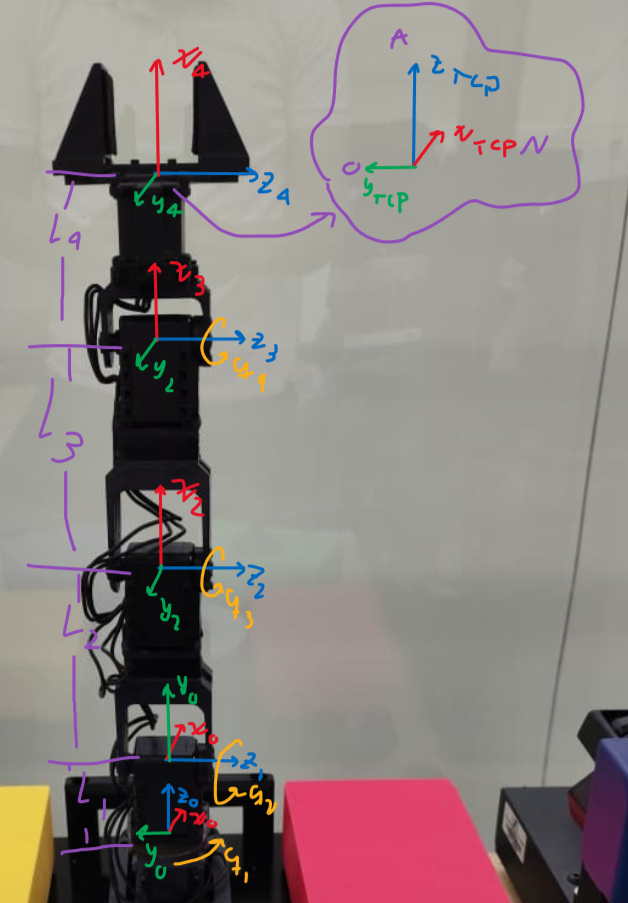

De modo que,

Ahora, para llegar al TCP


$$R_4^{\mathrm{TCP}} =R_{Z\left(-90\degree \right)} \;R_{X\left(-90\degree \right)}$$


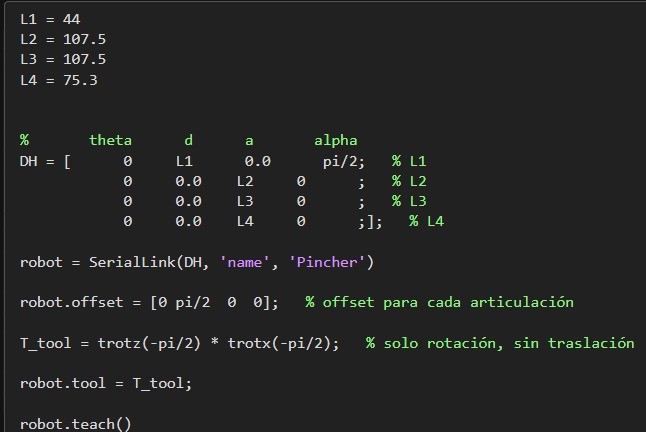

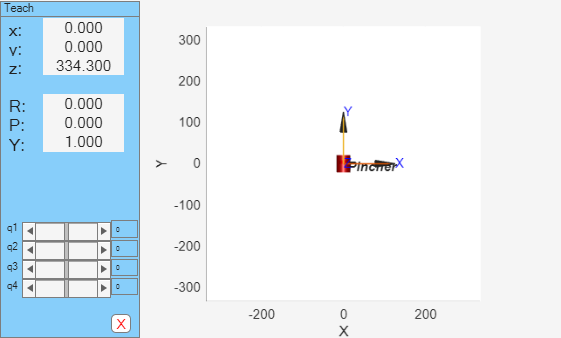

% --- Longitudes (pueden estar en mm, sólo sé coherente en todo) ---
L1 = 44;
L2 = 107.5;
L3 = 107.5;
L4 = 75.3;

% --- Definición correcta de las articulaciones (DH estándar) ---
% Link('revolute','d',d,'a',a,'alpha',alpha,'offset',offset)

L(1) = Link('revolute', ...
            'd',     L1, ...
            'a',     0, ...
            'alpha', pi/2, ...   % 90°
            'offset', 0);

L(2) = Link('revolute', ...
            'd',     0, ...
            'a',     L2, ...
            'alpha', 0, ...
            'offset', pi/2);     % offset de 90° según la tabla

L(3) = Link('revolute', ...
            'd',     0, ...
            'a',     L3, ...
            'alpha', 0, ...
            'offset', 0);

L(4) = Link('revolute', ...
            'd',     0, ...
            'a',     L4, ...
            'alpha', 0, ...
            'offset', 0);

% --- Crear el manipulador ---
robot = SerialLink(L, 'name', 'Pincher');

% --- Orientación de la herramienta (TCP) ---
T_tool = trotz(-pi/2) * trotx(-pi/2);   % Rz(-90°) Rx(-90°), sin traslación
robot.tool = T_tool;

% (Opcional) límites articulares, por ejemplo ±90°
robot.qlim = deg2rad([ -90  90;
                       -90  90;
                       -90  90;
                       -90  90 ]);

% --- Simulación interactiva ---
robot.teach();      % abre la ventana para mover q1..q4